Note: all functions used are included in this single mlx script for clarity

function draw2Dtruss(nodesCoordinates, connectivity, varargin)
% draw2Dtruss Draws a 2D truss structure with node and element labels
% 
% Usage:
%   draw2Dtruss(nodesCoordinates, connectivity)
%   draw2Dtruss(nodesCoordinates, connectivity, 'LineColor', 'r', 'Title', 'My Truss')
%
% Inputs:
%   nodesCoordinates - Nx2 matrix of node coordinates [x, y]
%   connectivity     - Mx2 matrix of node indices defining truss elements
%   varargin         - (Optional) name-value pairs:
%                      'LineColor' (default: 'b')
%                      'LineWidth' (default: 1)
%                      'MarkerSize' (default: 15)
%                      'FontSize' (default: 20)
%                      'ShowNodeNumbers' (default: false)
%                      'Title' (default: '2D Truss Structure')
    % Parse input options
    p = inputParser;
    addParameter(p, 'LineColor', 'b');
    addParameter(p, 'LineWidth', 1);
    addParameter(p, 'MarkerSize', 15);
    addParameter(p, 'ShowNodeNumbers', false);
    addParameter(p, 'Title', '2D Truss Structure');
    addParameter(p, 'FontSize', 2)
    parse(p, varargin{:});
    
    % Extract parsed options
    lineColor = p.Results.LineColor;
    lineWidth = p.Results.LineWidth;
    markerSize = p.Results.MarkerSize;
    showNodeNumbers = p.Results.ShowNodeNumbers;
    fontSize = p.Results.FontSize;
    titleText = p.Results.Title;
    figure; hold on; axis equal;
    xlabel('X'); ylabel('Y');
    title(titleText, 'Interpreter', 'none');
    % Plot truss elements
    for e = 1:size(connectivity, 1)
        n1 = connectivity(e, 1);
        n2 = connectivity(e, 2);
        x = [nodesCoordinates(n1, 1), nodesCoordinates(n2, 1)];
        y = [nodesCoordinates(n1, 2), nodesCoordinates(n2, 2)];
        plot(x, y, '-', 'Color', lineColor, 'LineWidth', lineWidth);
        % Midpoint of element
        midX = mean(x);
        midY = mean(y);
        % Plot white triangle with black edge at midpoint
        plot(midX, midY, '^', ...
            'MarkerSize', markerSize * 0.8, ...
            'MarkerEdgeColor', 'k', ...
            'MarkerFaceColor', 'w');
        % Label the truss element number (larger, black font)
        text(midX, midY, sprintf('%d', e), ...
            'Color', 'b', ...nodes
            'FontSize', fontSize, ...
            'FontWeight', 'bold', ...
            'HorizontalAlignment', 'center', ...
            'VerticalAlignment', 'middle');
    end
    % Plot nodes with white interior circles
    plot(nodesCoordinates(:,1), nodesCoordinates(:,2), 'o', ...
         'MarkerSize', markerSize, 'MarkerFaceColor', 'w', ...
         'MarkerEdgeColor', 'k', 'LineWidth', 1.2);
    % Node numbers inside the circle
    if showNodeNumbers
        for e = 1:size(nodesCoordinates, 1)
            text(nodesCoordinates(e,1), nodesCoordinates(e,2), ...
                sprintf('%d', e), ...
                'FontSize', fontSize, 'Color', 'k', ...
                'HorizontalAlignment', 'center', ...
                'VerticalAlignment', 'middle');
        end
    end
    grid on;
end

function [mass] = formConsistentMass2Dtruss(GDof, connectivity, nodesCoordinates, rho, A)
% Computes the assembled consistent mass matrix
mass=zeros(GDof);
numberOfElements = size(connectivity,1);
nodeCoordinateX = nodesCoordinates(:,1);
nodeCoordinateY = nodesCoordinates(:,2);
for e = 1:numberOfElements
    % elementDof: element degrees of freedom (Dof)
    localIndices = connectivity(e,:);
    elementDof = [2*localIndices(1)-1 2*localIndices(1) 2*localIndices(2)-1 2*localIndices(2)] ;
    xa = nodeCoordinateX(localIndices(2))-nodeCoordinateX(localIndices(1));
    ya = nodeCoordinateY(localIndices(2))-nodeCoordinateY(localIndices(1));
    elementLength = sqrt(xa*xa+ya*ya);
    C = xa/elementLength;
    S = ya/elementLength;
    
    elementaryMass = rho*A(e)*elementLength/6*[2*C*C 2*C*S C*C C*S; 2*C*S 2*S*S C*S S*S; C*C C*S 2*C*C 2*C*S;C*S S*S 2*C*S 2*S*S];
    
    mass(elementDof,elementDof) = mass(elementDof,elementDof) + elementaryMass;
end
end

function [stiffness,element_lengths] = formStiffness2Dtruss(GDof, connectivity, nodesCoordinates, E, A)
% Computes the assembled stiffness matrix
stiffness=zeros(GDof);
numberOfElements = size(connectivity,1);
nodeCoordinateX = nodesCoordinates(:,1);
nodeCoordinateY = nodesCoordinates(:,2);
element_lengths = zeros(numberOfElements,1);
for e = 1:numberOfElements
    % elementDof: element degrees of freedom (Dof)
    localIndices = connectivity(e,:);
    elementDof = [2*localIndices(1)-1 2*localIndices(1) 2*localIndices(2)-1 2*localIndices(2)] ;
    
    xa = nodeCoordinateX(localIndices(2))-nodeCoordinateX(localIndices(1));
    ya = nodeCoordinateY(localIndices(2))-nodeCoordinateY(localIndices(1));
    elementLength = sqrt(xa*xa+ya*ya);
    element_lengths(e)=elementLength;
    C = xa/elementLength;
    S = ya/elementLength;
    
    elementaryStiffness = E*A(e)/elementLength*[C*C C*S -C*C -C*S; C*S S*S -C*S -S*S;-C*C -C*S C*C C*S;-C*S -S*S C*S S*S];
    
    stiffness(elementDof,elementDof) = stiffness(elementDof,elementDof) + elementaryStiffness;
end
end

function [modes,omega] = computeFrequenciesAndModes(GDof,prescribedDof,stiffness,mass,maxEigenvalues)
% function to compute eigenvalues and eigenvectors
% GDof: number of degree of freedom
% prescribedDof: bounded boundary dofs
% stiffness: stiffness matrix
% mass: mass matrix
% maxEigenvalues: maximum eigenvalues to be computed. If 0 all the
% eigenvalues are requested (suggested for structures)
activeDof = setdiff(transpose((1:GDof)), prescribedDof);
if maxEigenvalues == 0
    [modes,D] = eig(stiffness(activeDof,activeDof),mass(activeDof,activeDof));
else
    [modes,D] = eigs(stiffness(activeDof,activeDof),mass(activeDof,activeDof),maxEigenvalues,'smallestabs');
end
eigenvalues = diag(D);
omega = sqrt(eigenvalues);
end

Start of own work here:

## Warren Truss

clear all
%Material Properties of Wood
E=12*10^9;
sigma_yield=30*10^6; 
rho=600;
n=25; %Total number of nodes in truss
m=47; %Total number of bars in the truss
A=100/10^4*ones(m,1); %Cross-sectional area of the bars
j=2*13; %Degree of freedom number where the force is applied (vertical force at node 13)
% Prescribed and free degrees of freedom (used for applying boundary
% conditions)
prescribedDof=[1,2,5,6,45,46,49,50];
freeDof=[3 4 7:44 47 48];

% Entering node coordinates for the Warren Truss
nodesCoordinates = zeros(n,2);
 
nodesCoordinates(1:4,:)=[0 0; 0.5 2; 1 0; 2 2];
for i = 1:9
    nodesCoordinates(3+2*i,:)=nodesCoordinates(1+2*i,:)+[2 0];
    nodesCoordinates(4+2*i,:)=nodesCoordinates(2+2*i,:)+[2 0];
end
nodesCoordinates(23,:)=nodesCoordinates(21,:)+[2 0];
nodesCoordinates(24,:)=nodesCoordinates(22,:)+[1.5 0];
nodesCoordinates(25,:)=nodesCoordinates(23,:)+[1 0];
nodesCoordinates

nodesCoordinates =          0         0
    0.5000    2.0000
    1.0000         0
    2.0000    2.0000
    3.0000         0
    4.0000    2.0000
    5.0000         0
    6.0000    2.0000
    7.0000         0
    8.0000    2.0000


% Forming connectivity table for the Warren Truss
connectivity=zeros(m,2);
for i = 1:11
    connectivity(4*i-3,:)=[2*i-1 2*i];
    connectivity(4*i-2,:)=[2*i-1 2*i+1];
    connectivity(4*i-1,:)=[2*i 2*i+1];
    connectivity(4*i,:)=[2*i 2*i+2];
end
    connectivity(45,:)=[23 24];
    connectivity(46,:)=[23 25];
    connectivity(47,:)=[24 25];
connectivity

connectivity =      1     2
     1     3
     2     3
     2     4
     3     4
     3     5
     4     5
     4     6
     5     6
     5     7


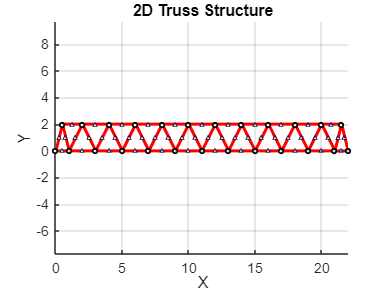

draw2Dtruss(nodesCoordinates, connectivity, ...
    'LineColor', 'r', ...
    'LineWidth', 2, ...
    'MarkerSize', 3, ...
    'ShowNodeNumbers', true);


GDof=2*n;%Total number of degrees of freedom (2 per node)

Define the fem analysis function which will be called for all subsequent iterations of bridge designs.


function [max_stress,q_scalarmax,safety_factors,freq,V,modal_matrix,nodeCoordinateX,nodeCoordinateY,stresses]=fem(GDof,connectivity,nodesCoordinates,E,A,sigma_yield,rho,n,m,j,freeDof,prescribedDof)
% compute and assemble the structure stiffness matrix
[stiffness, element_lengths] = formStiffness2Dtruss(GDof, connectivity, nodesCoordinates, E, A);
% compute and assemble the structure maass matrix
mass = formConsistentMass2Dtruss(GDof,connectivity, nodesCoordinates, rho, A);
%Perform Modal Analysis
[modal_matrix,frequencies] = computeFrequenciesAndModes(GDof,prescribedDof,stiffness,mass,0);
freq=frequencies/2/pi; %Get frequencies in Hertz
%Volume of material used
V=sum(A.*element_lengths);
%Perform Static Analysis Kq=f
f=zeros(GDof,1); %Forcing Vector
f(j)=-50000;%kN Vertical force at node 26
% Apply boundary conditions
f_red=f(freeDof);
stiffness_red=stiffness(freeDof,freeDof);
%Calculate displacements
q_red=linsolve(stiffness_red,f_red);
% Reinsert nodes with prescribed zero displacement into displacement vector
q=zeros(GDof,1);
q(freeDof)=q_red;
qmax=max(abs(q));%Maximum displacement [m]
find(abs(q)==qmax); 

% The displacement criterion states that scalar displacement at any node must not
% exceed 40mm, so we must take the euclidean norm of displacements at every
% node
q_scalar=zeros(n,1);
for i=1:n
    q_scalar(i)=sqrt(q(2*i-1).^2+q(2*i).^2);
end
q_scalarmax=max(q_scalar); % We will consider the maximum scalar displacement to check against the limit
find(q_scalar==q_scalarmax); % Find node index where maximum scalar displacement occurs
%Compute stresses in members
stress=zeros(m,1);
nodeCoordinateX = nodesCoordinates(:,1);
nodeCoordinateY = nodesCoordinates(:,2);
for e = 1:m
    nodes=connectivity(e,:);
    xa = nodeCoordinateX(nodes(2))-nodeCoordinateX(nodes(1));
    ya = nodeCoordinateY(nodes(2))-nodeCoordinateY(nodes(1));
    elementLength = sqrt(xa*xa+ya*ya);
    C = xa/elementLength;
    S = ya/elementLength;
    strain=([q(2*nodes(1)-1) q(2*nodes(1))]-[q(2*nodes(2)-1) q(2*nodes(2))])*[C; S]/elementLength; %Project difference in nodal displacements onto bar's axis and divide by bar length to get strain
    stress(e)=E*strain;
end
stresses=stress;
safety_factors=sigma_yield./(max(abs(stress),10^6)); %Want any bar to resist at least 10^6 Pa as vibrations could result in loading, also avoids large values in safety factors vector.
max_stress=max(abs(stress)); %
end

% Run iteration 1 simulation
[max_stress,q_scalarmax,safety_factors,freq,V,modal_matrix,nodeCoordinateX,nodeCoordinateY]=fem(GDof,connectivity,nodesCoordinates,E,A,sigma_yield,rho,n,m,j,freeDof,prescribedDof);
%Display design criteria: maximum stress, first natural frequency, material
%volume and maximum nodal displacement
disp(max_stress)

   1.0270e+07



disp(freq(1))

   23.8350



disp(V)

    0.9597



disp(q_scalarmax)

    0.0231



%The safety factors are excessive, could save on material
%Optimization
red=find(safety_factors<6) %Bars which experience highest loading

red =     16
    20
    24
    28
    32


yellow=find(safety_factors<10) %Next most critical bars

yellow =      1
     3
     6
    16
    20
    22
    24
    26
    28
    32


%Thin out all bars to 30cm2
A=30/10^4*ones(m,1);
A(yellow)=50/10^4; %Make moderately critical bars wider
A(red)=75/10^4; %Make most critical bars widest

Now rerunwith optimized bars:

%Run iteration 2
[max_stress,q_scalarmax,safety_factors,freq,V,modal_matrix]=fem(GDof,connectivity,nodesCoordinates,E,A,sigma_yield,rho,n,m,j,freeDof,prescribedDof);
%Display design criteria:
disp(max_stress)

   1.4150e+07



disp(freq(1))

   29.6862



disp(V)

    0.3654



disp(q_scalarmax)

    0.0495



%Problem: max displacement of 0.0495m violates l/500 criterion.
%While safety factors are okay, need to thicken bars in view of limiting
%displacements.
A=50/10^4*ones(m,1);
A(yellow)=50/10^4; %Make moderately critical bars wider
A(red)=75/10^4; %Make most critical bars widest

Third iteration:

[max_stress,q_scalarmax,safety_factors,freq,V,modal_matrix,nodeCoordinateX,nodeCoordinateY]=fem(GDof,connectivity,nodesCoordinates,E,A,sigma_yield,rho,n,m,j,freeDof,prescribedDof);
disp(max_stress)

   1.4306e+07



disp(freq(1))

   25.7596



disp(V)

    0.5048



disp(q_scalarmax)

    0.0395



%Displacement, stresses and material volume are all reasonable

Now we look at modal displacements under the first mode. The idea is to thicken bars which are most deform in order to hopefully increase the stiffness of the mode.

%Add blocked degrees of freedom back into first modal vector
mode1=zeros(GDof,1);
mode1(freeDof)=modal_matrix(:,1)

mode1 =          0
         0
   -0.0213
         0
         0
         0
   -0.0231
    0.0171
    0.0063
    0.0372


%Calculate elongation of bars due to mode 1
elongation=zeros(m,1);
for e = 1:m
    nodes=connectivity(e,:);
    xa = nodeCoordinateX(nodes(2))-nodeCoordinateX(nodes(1));
    ya = nodeCoordinateY(nodes(2))-nodeCoordinateY(nodes(1));
    elementLength = sqrt(xa*xa+ya*ya);
    C = xa/elementLength;
    S = ya/elementLength;
    elongation(e)=([mode1(2*nodes(1)-1) mode1(2*nodes(1))]-[mode1(2*nodes(2)-1) mode1(2*nodes(2))])*[C; S]; %Project difference in nodal displacements onto bar's axis and divide by bar length to get strain
end
elongation=abs(elongation);
elongation=elongation/max(elongation); %Scale so that most elongated bar elongates by 1
blue=find(elongation>0.8)%Most elongated bars

blue =      6
    20
    24
    28
    42


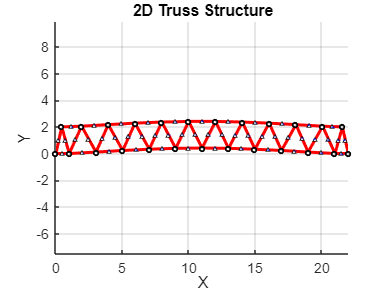

A(blue)=100/10^4; %Thicken bars which deform a lot under mode 1
%Plot bridge deformed under mode 1 by adding modal displacements to node
%coordinates
mode1_reshaped=zeros(n,2);
mode1_reshaped(:,1)=mode1(2*(1:n)-1);
mode1_reshaped(:,2)=mode1(2*(1:n));
nodesCoordinatesdef=nodesCoordinates+3*mode1_reshaped;
%Plot
draw2Dtruss(nodesCoordinatesdef, connectivity, ...
    'LineColor', 'r', ...
    'LineWidth', 2, ...
    'MarkerSize', 3, ...
    'ShowNodeNumbers', true);

Iteration 4:

[max_stress,q_scalarmax,safety_factors,freq,V,modal_matrix,nodeCoordinateX,nodeCoordinateY,stresses]=fem(GDof,connectivity,nodesCoordinates,E,A,sigma_yield,rho,n,m,j,freeDof,prescribedDof);
disp(max_stress)

   1.0905e+07



disp(freq(1))

   27.3769



disp(V)

    0.5398



disp(q_scalarmax)

    0.0348



%All is good, although frequency increase is very modest.

Visualize Modes 1 and 2 on final truss:

mode1=zeros(GDof,1);
mode1(freeDof)=modal_matrix(:,1)

mode1 =          0
         0
   -0.0221
         0
         0
         0
   -0.0240
    0.0183
    0.0039
    0.0384


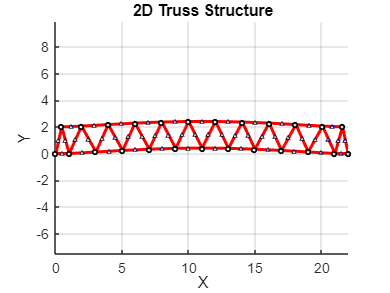

mode1_reshaped=zeros(n,2);
mode1_reshaped(:,1)=mode1(2*(1:n)-1);
mode1_reshaped(:,2)=mode1(2*(1:n));
nodesCoordinatesdef=nodesCoordinates+3*mode1_reshaped;
draw2Dtruss(nodesCoordinatesdef, connectivity, ...
    'LineColor', 'r', ...
    'LineWidth', 2, ...
    'MarkerSize', 3, ...
    'ShowNodeNumbers', true);

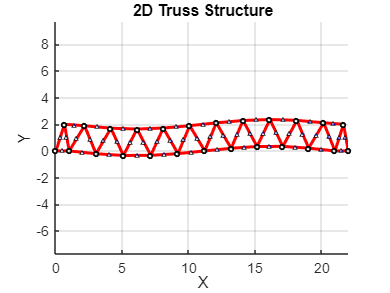


mode2=zeros(GDof,1);
mode2(freeDof)=modal_matrix(:,2);
mode2_reshaped=zeros(n,2);
mode2_reshaped(:,1)=mode2(2*(1:n)-1);
mode2_reshaped(:,2)=mode2(2*(1:n));
nodesCoordinatesdef=nodesCoordinates+3*mode2_reshaped;
draw2Dtruss(nodesCoordinatesdef, connectivity, ...
    'LineColor', 'r', ...
    'LineWidth', 2, ...
    'MarkerSize', 3, ...
    'ShowNodeNumbers', true);

Buckling Analysis of Bars (annular section with inner radius 90% of outer radius)

%Extract Lengths of all bars
elementLength=zeros(m,1);
for e = 1:m
    nodes=connectivity(e,:);
    xa = nodeCoordinateX(nodes(2))-nodeCoordinateX(nodes(1));
    ya = nodeCoordinateY(nodes(2))-nodeCoordinateY(nodes(1));
    elementLength(e) = sqrt(xa*xa+ya*ya);
end
elementLength;
rout=sqrt(A/pi/(1-0.9^2)); %Outer radius
rin=0.9*rout;
I=pi/4*(rout.^4-rin.^4); %Area moment of inertia of bars
Ncr=pi^2*E*I./elementLength.^2;%Critical buckling loads of bars
loads=(max(stresses,0)+1).*A; %Eliminate bars in tension and compute forces
S=Ncr./loads;
min(S)

ans = 16.0583

find(S==min(S))

ans = 3

% Bars 3 (and 45 by symmetry) experience greatest risk of buckling. Safety
% factor of 16.1 is sufficient.


Bridge 2 (Camelback):

E=69*10^9;
sigma_yield=200*10^6; %Yield strength of steel
rho=2700;
n=24; %Total number of nodes in truss
m=45; %Total number of bars in the truss
A=70/10^4*ones(m,1); %Cross-sectional area of the bars
j=2*12; %Degree of freedom number where the force is applied (vertical force at node 13)
prescribedDof=[1,2,5,6,45,46,47,48];
freeDof=[3 4 7:44];

% Entering node coordinates for Camelback Truss
nodesCoordinates = zeros(n,2);
 
nodesCoordinates(1,:)=[0 0];
nodesCoordinates(2,:)=[1 2];
nodesCoordinates(3,:)=[1 0];
for i = 2*(1:10)+3
    nodesCoordinates(i,:)=nodesCoordinates(i-2,:)+[2 0];
end
nodesCoordinates(24,:)=nodesCoordinates(23,:)+[1 0];
for i = 2*(1:3)+2
    nodesCoordinates(i,:)=nodesCoordinates(i-2,:)+[2 0.5];
end
for i = 2*(1:4)+8
    nodesCoordinates(i,:)=nodesCoordinates(i-2,:)+[2 0];
end
for i = 2*(1:3)+16
    nodesCoordinates(i,:)=nodesCoordinates(i-2,:)+[2 -0.5];
end
%Construct connectivity table
connectivity=zeros(m,2);
connectivity(1,:)=[1 2];
for i = 1:10
    connectivity(4*i-2,:)=[2*i-1 2*i+1];
    connectivity(4*i-1,:)=[2*i+1 2*i];
    connectivity(4*i,:)=[2*i 2*i+2];
end
for i = 1:5
    connectivity(4*i+1,:)=[2*i 2*i+3];
end
for i = 6:10
    connectivity(4*i+1,:)=[2*i+1 2*i+2];
end
connectivity(42,:)=[21 23];
connectivity(43,:)=[23 22];
connectivity(44,:)=[22 24];
connectivity(45,:)=[23 24];

connectivity

connectivity =      1     2
     1     3
     3     2
     2     4
     2     5
     3     5
     5     4
     4     6
     4     7
     5     7


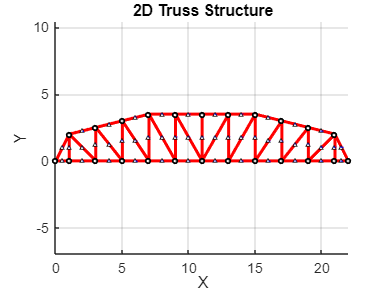

%Draw 2D Truss to check connectivity and coordinates
draw2Dtruss(nodesCoordinates, connectivity, ...
    'LineColor', 'r', ...
    'LineWidth', 2, ...
    'MarkerSize', 3, ...
    'ShowNodeNumbers', true);


GDof=2*n%Total number of degrees of freedom (2 per node)

GDof = 48

%Simulate first iteration of the truss
[max_stress,q_scalarmax,safety_factors,freq,V,modal_matrix,nodeCoordinateX,nodeCoordinateY]=fem(GDof,connectivity,nodesCoordinates,E,A,sigma_yield,rho,n,m,j,freeDof,prescribedDof);
disp(max_stress)

   9.9372e+06



disp(freq(1))

   25.6367



disp(V)

    0.8032



disp(q_scalarmax)

    0.0041



%Displacement, frequencies, material volume, stress all ok

%Begin by thinning out non critical bars (in terms of stress)
red=find(safety_factors<25) %Bars which experience highest loading

red =     20
    24


yellow=find(safety_factors<35) %Next most critical bars

yellow =     12
    16
    20
    23
    24
    28
    32


%Thin out all bars to 20cm2
A=20/10^4*ones(m,1);
A(yellow)=30/10^4; %Make moderately critical bars wider
A(red)=40/10^4; %Make most critical bars widest

Iteration 2

[max_stress,q_scalarmax,safety_factors,freq,V,modal_matrix,nodeCoordinateX,nodeCoordinateY]=fem(GDof,connectivity,nodesCoordinates,E,A,sigma_yield,rho,n,m,j,freeDof,prescribedDof)

max_stress = 1.9049e+07

q_scalarmax = 0.0115

safety_factors =   200.0000
  200.0000
   16.0072
   19.3985
   14.1429
   13.0441
   20.0011
   11.6404
   18.7419
   37.5015


freq = 1.0e+03 *

    0.0278
    0.0547
    0.0879
    0.0953
    0.1415
    0.1622
    0.1912
    0.2052
    0.2324
    0.2454


V = 0.2491

modal_matrix =    -0.0069   -0.0292    0.0283    0.0235    0.0340   -0.0587    0.0055    0.0552   -0.0407    0.0161    0.0977    0.0153    0.0253   -0.0388    0.1271    0.0309   -0.0190    0.0593   -0.1118   -0.0198    0.0399   -0.0307    0.0843   -0.0601    0.0776    0.0171    0.0465   -0.0022   -0.0344    0.0917    0.0098    0.0633   -0.0912    0.0151    0.1452    0.1572    0.0262    0.1203   -0.0045   -0.0501
    0.0035    0.0085    0.0022   -0.0119   -0.0167    0.0167   -0.0094    0.0054    0.0207   -0.0242    0.0034    0.0174   -0.0324    0.0238   -0.0127    0.0172   -0.0499   -0.0582   -0.0032    0.1086   -0.0308    0.1061   -0.0183   -0.0773    0.1485   -0.0627    0.0883    0.1365    0.0425    0.0399   -0.0845    0.0264    0.0561   -0.0030   -0.0263   -0.0041   -0.0103    0.0024    0.0070   -0.0019
   -0.0092   -0.0359    0.0362    0.0261    0.0328   -0.0593   -0.0070    0.0639   -0.0303   -0.0040    0.0925    0.0407   -0.0111   -0.0144    0.0687    0.0440   -0.0539   -0.0242   

nodeCoordinateX =      0
     1
     1
     3
     3
     5
     5
     7
     7
     9


nodeCoordinateY =          0
    2.0000
         0
    2.5000
         0
    3.0000
         0
    3.5000
         0
    3.5000


disp(max_stress)

   1.9049e+07



disp(freq(1))

   27.7667



disp(V)

    0.2491



disp(q_scalarmax)

    0.0115



% Displacement is still good and volume has been greatly reduced!

Optimizing natural frequency by increasing thickness of most elongated bars under mode 1:

%Look to increase 1st natural frequency currently at 28Hz
mode1=zeros(GDof,1);
mode1(freeDof)=modal_matrix(:,1)

mode1 =          0
         0
   -0.0069
    0.0035
         0
         0
   -0.0092
    0.0255
    0.0038
    0.0221


%Calculate elongation of bars due to mode 1
elongation=zeros(m,1);
for e = 1:m
    nodes=connectivity(e,:);
    xa = nodeCoordinateX(nodes(2))-nodeCoordinateX(nodes(1));
    ya = nodeCoordinateY(nodes(2))-nodeCoordinateY(nodes(1));
    elementLength = sqrt(xa*xa+ya*ya);
    C = xa/elementLength;
    S = ya/elementLength;
    elongation(e)=([mode1(2*nodes(1)-1) mode1(2*nodes(1))]-[mode1(2*nodes(2)-1) mode1(2*nodes(2))])*[C; S]; %Project difference in nodal displacements onto bar's axis and divide by bar length to get strain
end
elongation=abs(elongation);
elongation=elongation/max(elongation); %Scale so that most elongated bar elongates by 1
blue=find(elongation>0.8)%Most elongated bars

blue =      5
     8
    16
    28
    36
    41


A(blue)=50/10^4; %Thicken bars which deform a lot under mode 1
%Plot bridge deformed under mode 1
mode1_reshaped=zeros(n,2);
mode1_reshaped(:,1)=mode1(2*(1:n)-1);
mode1_reshaped(:,2)=mode1(2*(1:n));
nodesCoordinatesdef=nodesCoordinates+20*mode1_reshaped;

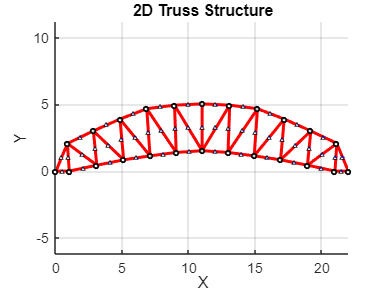

%Plot funadmental deformation mode
draw2Dtruss(nodesCoordinatesdef, connectivity, ...
    'LineColor', 'r', ...
    'LineWidth', 2, ...
    'MarkerSize', 3, ...
    'ShowNodeNumbers', true)

Iteration 3

[max_stress,q_scalarmax,safety_factors,freq,V,modal_matrix,nodeCoordinateX,nodeCoordinateY]=fem(GDof,connectivity,nodesCoordinates,E,A,sigma_yield,rho,n,m,j,freeDof,prescribedDof);
disp(max_stress)

   1.8064e+07



disp(freq(1))

   30.6588



disp(V)

    0.2864



disp(q_scalarmax)

    0.0102



% Slight increase to 31Hz

We now try a different approach to increase natural frequency: adding extra bars!

n=24; %Total number of nodes in truss
m=m+2; %Total number of bars in the truss
% Define cross-sectional area of the two extra bars
Anew=ones(m,1);
Anew(1:m-2)=A;
Anew(m-1)=30/10^4;
Anew(m)=Anew(m-1)

Anew =     0.0020
    0.0020
    0.0020
    0.0020
    0.0050
    0.0020
    0.0020
    0.0050
    0.0020
    0.0020


A=Anew;
%Add two new bars to connectivity table
connectivity=zeros(m,2);
connectivity(1,:)=[1 2];
for i = 1:10
    connectivity(4*i-2,:)=[2*i-1 2*i+1];
    connectivity(4*i-1,:)=[2*i+1 2*i];
    connectivity(4*i,:)=[2*i 2*i+2];
end
for i = 1:5
    connectivity(4*i+1,:)=[2*i 2*i+3];
end
for i = 6:10
    connectivity(4*i+1,:)=[2*i+1 2*i+2];
end
connectivity(42,:)=[21 23];
connectivity(43,:)=[23 22];
connectivity(44,:)=[22 24];
connectivity(45,:)=[23 24];
connectivity(46,:)=[3 4];
connectivity(47,:)=[20 23];

connectivity

connectivity =      1     2
     1     3
     3     2
     2     4
     2     5
     3     5
     5     4
     4     6
     4     7
     5     7


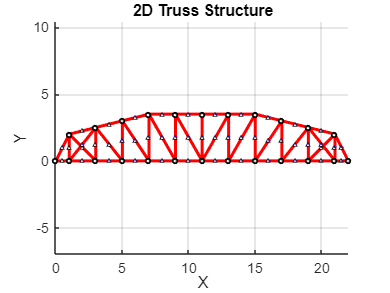

draw2Dtruss(nodesCoordinates, connectivity, ...
    'LineColor', 'r', ...
    'LineWidth', 2, ...
    'MarkerSize', 3, ...
    'ShowNodeNumbers', true);

%Run analysis
[max_stress,q_scalarmax,safety_factors,freq,V,modal_matrix,nodeCoordinateX,nodeCoordinateY,stresses]=fem(GDof,connectivity,nodesCoordinates,E,A,sigma_yield,rho,n,m,j,freeDof,prescribedDof);
disp(max_stress)

   1.7594e+07



disp(freq(1))

   34.3071



disp(V)

    0.3056



disp(q_scalarmax)

    0.0090



% Some increase in natural frequency with only minor increase in volume,
% approach is moderately successful

Buckling Analysis of Bars (annular section with inner radius 90% of outer radius)

%Extract Lengths of all bars
elementLength=zeros(m,1)

elementLength =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for e = 1:m
    nodes=connectivity(e,:);
    xa = nodeCoordinateX(nodes(2))-nodeCoordinateX(nodes(1));
    ya = nodeCoordinateY(nodes(2))-nodeCoordinateY(nodes(1));
    elementLength(e) = sqrt(xa*xa+ya*ya);
end
elementLength;
rout=sqrt(Anew/pi/(1-0.9^2)); %Outer radius
rin=0.9*rout;
I=pi/4*(rout.^4-rin.^4); %Area moment of inertia of bars
Ncr=pi^2*E*I./elementLength.^2;%Critical buckling loads of bars
loads=(max(stresses,0)+1).*Anew; %Eliminate bars in tension and compute forces
S=Ncr./loads;
min(S)

ans = 6.7429

find(S==min(S))

ans = 27

% Bars 27 (and 19 by symmetry) experience greatest risk of buckling. Safety
% factor of 6.7 is sufficient.

Part 3 Pratt Truss (code has been organized a bit differently as we worked separately):

% Bridge 3 : Steel Pratt Truss

E=200*10^9;
sigma_yield=250*10^6; %Yield strength of mild steel
rho=7850;
n=16; %Total number of nodes in truss
m=29; %Total number of bars in the truss
A=30/10^4*ones(m,1); %Cross-sectional area of the bars
j=2*8; %Degree of freedom number where the force is applied (vertical force at node 8)
GDof=2*n  %Total number of degrees of freedom (2 per node)

GDof = 32

%Apply boundary conditions 
prescribedDof=[1, 2, 5, 6 , 29, 30 , 31, 32];
freeDof = [3 4 7:28];

% Nodes Coordinates 
nodesCoordinates = zeros(n,2);
 
nodesCoordinates(1,:)=[0 0];
nodesCoordinates(2,:)=[1 2];
nodesCoordinates(3,:)=[1 0];
for i = 2:7
    nodesCoordinates(2*i+1,:)=nodesCoordinates(1+2*(i-1),:)+[(10/3) 0];
    nodesCoordinates(2*i,:)=nodesCoordinates(2*(i-1),:)+[(10/3) 0];
end
nodesCoordinates(16,:)=[22 0];


connectivity = zeros(m,2);
c = 1;  % Compteur pour remplir la matrice
connectivity(c,:) = [1, 2];
c = c + 1;
% (b) Corde du bas (8 segments) : (1->3), (3->5), (5->7), (7->9), (9->11), (11->13), (13->15), (15->16)
for i = [1,3,5,7,9,11,13,15]
    % Pour i = 15, on connecte 15->16.
    if i < 15
        connectivity(c,:) = [i, i+2];
    else
        connectivity(c,:) = [15, 16];
    end
    c = c + 1;
end
% (c) Corde du haut (6 segments) : (2->4), (4->6), (6->8), (8->10), (10->12), (12->14)
for i = 2:2:12
    connectivity(c,:) = [i, i+2];
    c = c + 1;
end
% (d) Montants (7) : (2->3), (4->5), (6->7), (8->9), (10->11), (12->13), (14->15)
for i = 2:2:14
    connectivity(c,:) = [i, i+1];
    c = c + 1;
end
% Diagonales inversées pour la 1ère moitié (3,5,7)
for i = 2:2:6
    connectivity(c,:) = [i, i+3]; 
    c = c + 1;
end
% Diagonales standard pour la 2ème moitié (9,11,13)
for i = 9:2:13
    connectivity(c,:) = [i, i+1];  % bottom -> top
    c = c + 1;
end
% (f) Montant d'extrémité droit : 14->16
connectivity(c,:) = [14, 16];
c = c + 1;
disp('=== Connectivity matrix ===');

=== Connectivity matrix ===


disp(connectivity);

     1     2
     1     3
     3     5
     5     7
     7     9
     9    11
    11    13
    13    15
    15    16
     2     4
     4     6
     6     8
     8    10
    10    12
    12    14
     2     3
     4     5
     6     7
     8     9
    10    11
    12    13
    14    15
     2     5
     4     7
     6     9
     9    10
    11    12
    13    14
    14    16



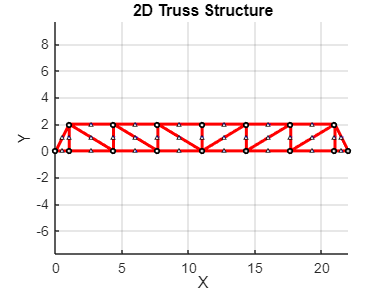


draw2Dtruss(nodesCoordinates, connectivity, ...
    'LineColor', 'r', ...
    'LineWidth', 2, ...
    'MarkerSize', 3, ...
    'ShowNodeNumbers', true);



% compute and assemble the structure stiffness matrix
[stiffness, element_lengths] = formStiffness2Dtruss(GDof, connectivity, nodesCoordinates, E, A)

stiffness = 1.0e+08 *

    6.5367    1.0733   -0.5367   -1.0733   -6.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.0733    2.1466   -1.0733   -2.1466         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -0.5367   -1.0733    3.4716    0.3924         0         0   -1.8000         0   -1.1349    0.6810         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -1.0733   -

element_lengths =     2.2361
    1.0000
    3.3333
    3.3333
    3.3333
    3.3333
    3.3333
    3.3333
    1.0000
    3.3333


% compute and assemble the structure maass matrix
mass = formConsistentMass2Dtruss(GDof,connectivity, nodesCoordinates, rho, A)

mass =    11.3606    7.0213    1.7553    3.5106    3.9250         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    7.0213   14.0425    3.5106    7.0213         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.7553    3.5106   52.1150   -6.4414         0         0   13.0833         0   11.2189   -6.7313         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    3.5106    7.0213   -6.4414




% For iteration 1 , 2 , 3 We change modify the cross section A=50, A=40 ,
% A=30

%Perform Modal Analysis
[modal_matrix,frequencies] = computeFrequenciesAndModes(GDof,prescribedDof,stiffness,mass,0)

modal_matrix =     0.0104    0.0221   -0.0074   -0.0132    0.0355    0.0137   -0.0143    0.0184   -0.0494    0.0098    0.0606   -0.0002   -0.0472    0.0183    0.0505    0.0069    0.0219    0.0654    0.0382    0.0087    0.0260    0.0256    0.0111   -0.0090
   -0.0028   -0.0054   -0.0011    0.0068   -0.0067   -0.0076   -0.0012   -0.0050    0.0069    0.0073   -0.0187   -0.0188    0.0192    0.0193    0.0109    0.1091    0.1124    0.0295    0.0045    0.0021   -0.0089   -0.0070   -0.0086    0.0063
    0.0089    0.0207   -0.0215    0.0064    0.0352   -0.0095   -0.0270    0.0075   -0.0368    0.0318   -0.0072   -0.0422    0.0228    0.0316   -0.0187    0.0036   -0.0084   -0.0548   -0.0477   -0.0202   -0.0320   -0.0358   -0.0025    0.0034
   -0.0326   -0.0353   -0.0504    0.0691    0.0159   -0.0554   -0.0456    0.0346   -0.0221   -0.0114    0.0213    0.0077   -0.0133    0.0012    0.0067   -0.0119   -0.0097    0.0064    0.0044   -0.0016   -0.1213   -0.1103   -0.0868    0.0705
   -0.0025    0.0094 

frequencies = 1.0e+03 *

    0.1849
    0.3942
    0.6093
    0.8489
    1.0940
    1.1713
    1.4707
    1.5684
    1.8264
    2.0781


freq=frequencies/2/pi %Get frequencies in Hertz

freq = 1.0e+03 *

    0.0294
    0.0627
    0.0970
    0.1351
    0.1741
    0.1864
    0.2341
    0.2496
    0.2907
    0.3307


%Volume of material used
V=sum(A.*element_lengths)

V = 0.2514

%Perform Static Analysis Kq=f
f=zeros(GDof,1) %Forcing Vector

f =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


f(8)=-50000%kN Vertical force at node 8

f =            0
           0
           0
           0
           0
           0
           0
      -50000
           0
           0


% Apply boundary conditions
f_red=f(freeDof)

f_red =            0
           0
           0
      -50000
           0
           0
           0
           0
           0
           0


stiffness_red=stiffness(freeDof,freeDof)

stiffness_red = 1.0e+08 *

    3.4716    0.3924   -1.8000         0   -1.1349    0.6810         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.3924    5.5552         0         0    0.6810   -0.4086         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -1.8000         0    4.7349   -0.6810         0         0   -1.8000         0   -1.1349    0.6810         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0   -0.6810    3.4086         0   -3.0000         0         0    0.6810   -0.4086         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -1.134

%Calculate displacements
q_red=linsolve(stiffness_red,f_red)

q_red =     0.0007
   -0.0002
    0.0004
   -0.0029
   -0.0002
   -0.0027
    0.0002
   -0.0032
    0.0001
   -0.0033


% Reinsert nodes with prescribed zero displacement into displacement vector
q=zeros(GDof,1);
q(freeDof)=q_red;
qmax=max(abs(q));%Maximum displacement [m]
find(abs(q)==qmax); %Maximum displacement is the vertical displacement where force is applied!

% The displacement criterion states that scalar displacement at any node must not
% exceed 40mm, so we must take the euclidean norm of displacements at every
% node
q_scalar=zeros(n,1);
for i=1:n
    q_scalar(i)=sqrt(q(2*i-1).^2+q(2*i).^2);
end
q_scalarmax=max(q_scalar)

q_scalarmax = 0.0033

find(q_scalar==q_scalarmax)

ans = 7



%Compute stresses in members
stress=zeros(m,1)

stress =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


nodeCoordinateX = nodesCoordinates(:,1);
nodeCoordinateY = nodesCoordinates(:,2);
for e = 1:m
    nodes=connectivity(e,:);
    xa = nodeCoordinateX(nodes(2))-nodeCoordinateX(nodes(1));
    ya = nodeCoordinateY(nodes(2))-nodeCoordinateY(nodes(1));
    elementLength = sqrt(xa*xa+ya*ya);
    C = xa/elementLength;
    S = ya/elementLength;
    strain=([q(2*nodes(1)-1) q(2*nodes(1))]-[q(2*nodes(2)-1) q(2*nodes(2))])*[C; S]/elementLength; %Project difference in nodal displacements onto bar's axis and divide by bar length to get strain
    stress(e)=E*strain;
end
stress

stress = 1.0e+07 *

   -1.0030
         0
    1.0127
   -1.3310
   -0.8970
   -0.0289
    0.4051
    0.8391
         0
    1.8952



safety_factors=sigma_yield./(max(abs(stress),10^7)) %Want any bar to resist at least 10^7 Pa as vibrations could result in loading

safety_factors =    24.9261
   25.0000
   24.6857
   18.7826
   25.0000
   25.0000
   25.0000
   25.0000
   25.0000
   13.1912


max_stress=max(abs(stress)) %In Pa

max_stress = 2.7333e+07



% Compute stresses in members
stress = zeros(m, 1);
nodeCoordinateX = nodesCoordinates(:, 1);
nodeCoordinateY = nodesCoordinates(:, 2);
for e = 1:m
    nodes = connectivity(e, :);
    xa = nodeCoordinateX(nodes(2)) - nodeCoordinateX(nodes(1));
    ya = nodeCoordinateY(nodes(2)) - nodeCoordinateY(nodes(1));
    elementLength = sqrt(xa * xa + ya * ya);
    C = xa / elementLength;
    S = ya / elementLength;
    strain = ([q(2 * nodes(1) - 1) q(2 * nodes(1))] - [q(2 * nodes(2) - 1) q(2 * nodes(2))]) * [C; S] / elementLength; % Project difference in nodal displacements onto bar's axis and divide by bar length to get strain
    stress(e) = E * strain;
end

% Safety factors and stress
safety_factors = sigma_yield ./ (max(abs(stress), 10^6)); % Want any bar to resist at least 10^6 Pa as vibrations could result in loading
max_stress = max(abs(stress)); % In Pa


% Iteration 4 (see report)

distances = zeros(m, 1);
for e = 1:m
    nodes = connectivity(e, :);
    mid_point = (nodesCoordinates(nodes(1), :) + nodesCoordinates(nodes(2), :)) / 2;
    % Calcul de la distance entre le point médian de la barre et le centre du treillis
    distances(e) = sqrt((mid_point(1) - nodesCoordinates(8, 1))^2 + (mid_point(2) - nodesCoordinates(8, 2))^2);
end

% Seuil de distance pour ajuster les sections
threshold_distance = max(distances) * 0.3; % 30% de la distance maximale pour déterminer les barres proches du centre

% Barres proches du centre auront des sections plus grandes
center_bars = find(distances <= threshold_distance); 

% Barres éloignées du centre auront des sections plus petites
outer_bars = find(distances > threshold_distance);

% Augmenter la section des barres proches du centre (forces plus importantes)
A(center_bars) = 50 / 10^4; % Augmenter la section des barres proches du centre

% Diminuer la section des barres éloignées du centre (forces plus faibles)
A(outer_bars) = 30 / 10^4; % Diminuer la section des barres éloignées du centre


% Optionally: Recompute stiffness and mass matrices with updated cross-sections
[stiffness2, element_lengths] = formStiffness2Dtruss(GDof, connectivity, nodesCoordinates, E, A);
mass2 = formConsistentMass2Dtruss(GDof, connectivity, nodesCoordinates, rho, A);

% Continue with modal and static analysis as before
%Perform Modal Analysis
[modal_matrix2,frequencies2] = computeFrequenciesAndModes(GDof,prescribedDof,stiffness2,mass2,0)

modal_matrix2 =     0.0092   -0.0207   -0.0005   -0.0147    0.0388   -0.0141   -0.0255    0.0137   -0.0468    0.0107    0.0567    0.0006   -0.0147    0.0489    0.0510   -0.0220    0.0256    0.0640    0.0328    0.0117   -0.0164   -0.0246    0.0230   -0.0116
   -0.0025    0.0049   -0.0027    0.0070   -0.0071    0.0072    0.0067    0.0012    0.0057    0.0081   -0.0180   -0.0196   -0.0176   -0.0185    0.0040    0.0873    0.1128    0.0722    0.0031    0.0019    0.0012    0.0088   -0.0112    0.0069
    0.0075   -0.0208   -0.0148    0.0047    0.0370    0.0071   -0.0118    0.0251   -0.0396    0.0339   -0.0084   -0.0438   -0.0313   -0.0227   -0.0245    0.0246   -0.0104   -0.0461   -0.0411   -0.0244    0.0299    0.0294   -0.0209    0.0075
   -0.0298    0.0263   -0.0554    0.0716    0.0205    0.0576   -0.0293    0.0428   -0.0246   -0.0087    0.0199    0.0082   -0.0008    0.0130    0.0081   -0.0144   -0.0095    0.0016    0.0034   -0.0061    0.0447    0.1142   -0.1326    0.0804
   -0.0022   -0.0109

frequencies2 = 1.0e+03 *

    0.1764
    0.3762
    0.5769
    0.8498
    1.2067
    1.2098
    1.5395
    1.5420
    1.7684
    2.1382


freq2=frequencies2/2/pi %Get frequencies in Hertz

freq2 = 1.0e+03 *

    0.0281
    0.0599
    0.0918
    0.1353
    0.1921
    0.1925
    0.2450
    0.2454
    0.2815
    0.3403


%Volume of material used
V2=sum(A.*element_lengths)

V2 = 0.2976

%Perform Static Analysis Kq=f
f2=zeros(GDof,1) %Forcing Vector

f2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


f2(8)=-50000%kN Vertical force at node 8

f2 =            0
           0
           0
           0
           0
           0
           0
      -50000
           0
           0


% Apply boundary conditions
f_red2=f2(freeDof)

f_red2 =            0
           0
           0
      -50000
           0
           0
           0
           0
           0
           0


stiffness_red2=stiffness2(freeDof,freeDof)

stiffness_red2 = 1.0e+08 *

    3.4716    0.3924   -1.8000         0   -1.1349    0.6810         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.3924    5.5552         0         0    0.6810   -0.4086         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -1.8000         0    4.7349   -0.6810         0         0   -1.8000         0   -1.1349    0.6810         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0   -0.6810    3.4086         0   -3.0000         0         0    0.6810   -0.4086         0         0         0         0         0         0         0         0         0         0         0         0         0         0
   -1.13

%Calculate displacements
q_red2=linsolve(stiffness_red2,f_red2)

q_red2 =     0.0006
   -0.0002
    0.0003
   -0.0027
   -0.0002
   -0.0026
    0.0001
   -0.0029
    0.0001
   -0.0029


% Reinsert nodes with prescribed zero displacement into displacement vector
q2=zeros(GDof,1);
q2(freeDof)=q_red2

q2 =          0
         0
    0.0006
   -0.0002
         0
         0
    0.0003
   -0.0027
   -0.0002
   -0.0026


qmax2=max(abs(q2))%Maximum displacement [m]

qmax2 = 0.0029

find(abs(q2)==qmax2) %Maximum displacement is the vertical displacement where force is applied!

ans = 14


% The displacement criterion states that scalar displacement at any node must not
% exceed 40mm, so we must take the euclidean norm of displacements at every
% node
q_scalar2=zeros(n,1);
for i=1:n
    q_scalar2(i)=sqrt(q2(2*i-1).^2+q2(2*i).^2);
end
q_scalar2

q_scalar2 =          0
    0.0007
         0
    0.0027
    0.0026
    0.0029
    0.0029
    0.0026
    0.0026
    0.0019


q_scalarmax2=max(q_scalar2)

q_scalarmax2 = 0.0029

find(q_scalar2==q_scalarmax2)

ans = 7

%Compute stresses in members
stress2=zeros(m,1)

stress2 =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


nodeCoordinateX = nodesCoordinates(:,1);
nodeCoordinateY = nodesCoordinates(:,2);
for e = 1:m
    nodes=connectivity(e,:);
    xa = nodeCoordinateX(nodes(2))-nodeCoordinateX(nodes(1));
    ya = nodeCoordinateY(nodes(2))-nodeCoordinateY(nodes(1));
    elementLength = sqrt(xa*xa+ya*ya);
    C = xa/elementLength;
    S = ya/elementLength;
    strain=([q2(2*nodes(1)-1) q2(2*nodes(1))]-[q2(2*nodes(2)-1) q2(2*nodes(2))])*[C; S]/elementLength; %Project difference in nodal displacements onto bar's axis and divide by bar length to get strain
    stress2(e)=E*strain;
end
stress2

stress2 = 1.0e+07 *

   -0.8551
         0
    0.9246
   -1.4135
   -0.5843
   -0.0567
    0.3452
    0.7848
         0
    1.9557



safety_factors2=sigma_yield./(max(abs(stress2),10^7)) %Want any bar to resist at least 10^7 Pa as vibrations could result in loading

safety_factors2 =    25.0000
   25.0000
   25.0000
   17.6861
   25.0000
   25.0000
   25.0000
   25.0000
   25.0000
   12.7832


max_stress2=max(abs(stress2)) %In Pa

max_stress2 = 2.7267e+07


%Add blocked degrees of freedom back into first modal vector
mode1=zeros(GDof,1);
mode1(freeDof)=modal_matrix(:,1)

mode1 =          0
         0
    0.0104
   -0.0028
         0
         0
    0.0089
   -0.0326
   -0.0025
   -0.0317


%Calculate elongation of bars due to mode 1
elongation=zeros(m,1);
for e = 1:m
    nodes=connectivity(e,:);
    xa = nodeCoordinateX(nodes(2))-nodeCoordinateX(nodes(1));
    ya = nodeCoordinateY(nodes(2))-nodeCoordinateY(nodes(1));
    elementLength = sqrt(xa*xa+ya*ya);
    C = xa/elementLength;
    S = ya/elementLength;
    elongation(e)=([mode1(2*nodes(1)-1) mode1(2*nodes(1))]-[mode1(2*nodes(2)-1) mode1(2*nodes(2))])*[C; S]; %Project difference in nodal displacements onto bar's axis and divide by bar length to get strain
end
elongation=abs(elongation);
elongation=elongation/max(elongation) %Scale so that most elongated bar elongates by 1

elongation =     0.4355
         0
    0.4939
    0.0579
    0.4360
    0.4360
    0.0579
    0.4939
         0
    0.3077


blue=find(elongation>0.8)%Most elongated bars

blue =     12
    13


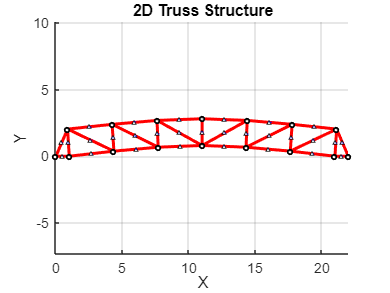

A(blue)=100/10^4; %Thicken bars which deform a lot under mode 1

%Plot bridge deformed under mode 1

amplification_factor = 12; % Facteur d'amplification ajustable pour mieux voir les déformations
mode1_reshaped = zeros(n, 2);
mode1_reshaped(:, 1) = mode1(2 * (1:n) - 1);
mode1_reshaped(:, 2) = mode1(2 * (1:n));
nodesCoordinatesdef = nodesCoordinates - amplification_factor * mode1_reshaped;

draw2Dtruss(nodesCoordinatesdef, connectivity, ...
    'LineColor', 'r', ...
    'LineWidth', 2, ...
    'MarkerSize', 3, ...
    'ShowNodeNumbers', true);


% Visualize Modes 1 and 2 on final truss:

mode1=zeros(GDof,1);
mode1(freeDof)=modal_matrix(:,1);
mode1_reshaped=zeros(n,2);
mode1_reshaped(:,1)=mode1(2*(1:n)-1);
mode1_reshaped(:,2)=mode1(2*(1:n));
nodesCoordinatesdef = nodesCoordinates-amplification_factor*mode1_reshaped;   %amplification factor to se better on plot


draw2Dtruss(nodesCoordinatesdef, connectivity, ...
    'LineColor', 'r', ...
    'LineWidth', 2, ...
    'MarkerSize', 3, ...
    'ShowNodeNumbers', true);


mode2=zeros(GDof,1);
mode2(freeDof)=modal_matrix(:,2);
mode2_reshaped=zeros(n,2);
mode2_reshaped(:,1)=mode2(2*(1:n)-1)

mode2_reshaped =          0         0
    0.0221         0
         0         0
    0.0207         0
    0.0094         0
    0.0180         0
    0.0205         0
    0.0187         0
    0.0278         0
    0.0180         0


mode2_reshaped(:,2)=mode2(2*(1:n))

mode2_reshaped =          0         0
    0.0221   -0.0054
         0         0
    0.0207   -0.0353
    0.0094   -0.0349
    0.0180   -0.0310
    0.0205   -0.0323
    0.0187    0.0000
    0.0278    0.0000
    0.0180    0.0310


nodesCoordinatesdef=nodesCoordinates+amplification_factor*mode2_reshaped     %amplification factor to se better on plot

nodesCoordinatesdef =          0         0
    1.2650    1.9348
    1.0000         0
    4.5820    1.5769
    4.4465   -0.4182
    7.8830    1.6278
    7.9129   -0.3874
   11.2238    2.0000
   11.3339    0.0000
   14.5497    2.3722


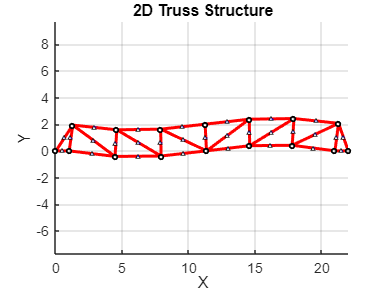


draw2Dtruss(nodesCoordinatesdef, connectivity, ...
    'LineColor', 'r', ...
    'LineWidth', 2, ...
    'MarkerSize', 3, ...
    'ShowNodeNumbers', true);